# Thermoeconomic Diagnosis Demo

Use ThermoeconomicDiagnosis function to compare two states of the plant ans make diagnosis

#### Select and check the model file

file="D:\Documents\Termoeconomia\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(4));
DiagnosisMethod='WASTE_INTERNAL';

#### Compute Cost Analysis

res=ThermoeconomicDiagnosis(data,'State',State,'DiagnosisMethod',DiagnosisMethod);

#### Show Results

res.summaryDiagnosis;

Fuel Impact:    -0.6900 (kW)
Malfunction Cost:     6.2277 (kW)


printResults(res);

Diagnosis Summary

Key        MF(kW)      ΔI(kW)     ΔPt(kW)     MF*(kW)     MR*(kW)    ΔPs*(kW)
——————————————————————————————————————————————————————————————————————————————
BLR       -0.4102     -0.4820      0.0000     -0.4102     -0.0917      0.0000
TRB        3.9841      2.9100     -3.2700      5.5999      1.0132     -6.9177
IHE        0.0389      0.1220      0.0000      0.0570      0.0345      0.0000
PMP        0.0000      0.0000      0.0000      0.0000      0.0019      0.0000
CND       -0.0000      0.0300      0.0000      0.0150      0.0082      0.0000
ENV        3.6128      2.5800     -3.2700      5.2617      0.9660     -6.9177


Malfunction Table (kW)

               BLR        TRB        IHE        PMP        CND        ΔPt
——————————————————————————————————————————————————————————————————————————
 BLR        0.0000     3.6118     0.0315     0.0000    -0.0257     0.0000
 TRB        0.0000     0.0000     0.0000     0.0000     0.0000    -3.2700
 IHE        0.0000     0.2651    

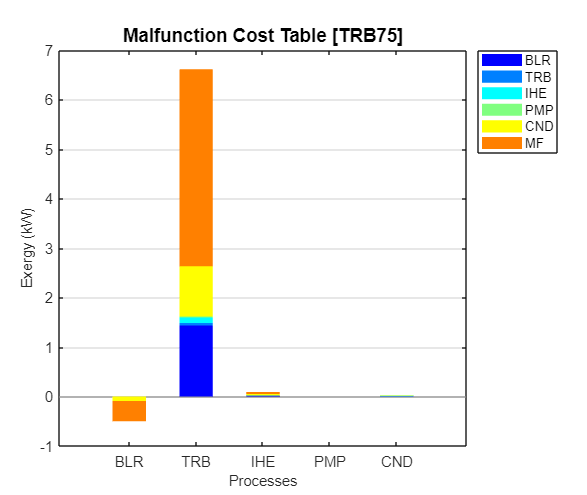

showGraph(res,'mfc',false);